clear all;
close all;
clc;

## Load the data

HK_CR_R_all_G = load("HK_CR_R_all.mat").HK_CR_R_all;
HK_CR_R_recall_values_all_G = load("HK_CR_R_recall_values_all.mat").HK_CR_R_recall_values_all;
HK_CG_G_all_G = load("HK_CG_G_all.mat").HK_CG_G_all;
HK_CG_G_recall_values_all_G = load("HK_CG_G_recall_values_all.mat").HK_CG_G_recall_values_all;
HK_CG_G_recall_norm_all = load('HK_CG_G_recall_norm_all.mat');
HK_CG_G_recall_norm_all = HK_CG_G_recall_norm_all.HK_CG_G_recall_norm_all;
HK_CR_R_recall_norm_all = load('HK_CR_R_recall_norm_all.mat');
HK_CR_R_recall_norm_all = HK_CR_R_recall_norm_all.HK_CR_R_recall_norm_all;
results_LocalT2 = load("results_LocalT2.mat");
results_LocalGini = load("results_LocalGini.mat");


## Obtain the name and change the name for LocalT2

fieldNames = fieldnames(results_LocalT2);
for i = 1:length(fieldNames)
    assignin('base', fieldNames{i}, results_LocalT2.(fieldNames{i}));
end
mean_HK_CG_G_all_LT2 = mean_HK_CG_G_all;
mean_HK_CG_G_recall_values_all_LT2 = mean_HK_CG_G_recall_values_all;
mean_HK_CR_R_all_LT2 = mean_HK_CR_R_all;
mean_HK_CR_R_recall_values_all_LT2 = mean_HK_CR_R_recall_values_all;
std_HK_CG_G_all_LT2 = std_HK_CG_G_all;
std_HK_CG_G_recall_values_all_LT2 = std_HK_CG_G_recall_values_all;
std_HK_CR_R_all_LT2 = std_HK_CR_R_all;
std_HK_CR_R_recall_values_all_LT2 = std_HK_CR_R_recall_values_all;
mean_HK_CR_R_recall_norm_all_LT2 = mean_HK_CR_R_recall_norm_all;
std_HK_CR_R_recall_norm_all_LT2 = std_HK_CR_R_recall_norm_all;

## Obtain the name and change the name for LocalGini

fieldNames = fieldnames(results_LocalGini);
for i = 1:length(fieldNames)
    assignin('base', fieldNames{i}, results_LocalGini.(fieldNames{i}));
end
mean_HK_CG_G_all_LG = mean_HK_CG_G_all;
mean_HK_CG_G_recall_values_all_LG = mean_HK_CG_G_recall_values_all;
mean_HK_CR_R_all_LG = mean_HK_CR_R_all;
mean_HK_CR_R_recall_values_all_LG = mean_HK_CR_R_recall_values_all;
std_HK_CG_G_all_LG = std_HK_CG_G_all;
std_HK_CG_G_recall_values_all_LG = std_HK_CG_G_recall_values_all;
std_HK_CR_R_all_LG = std_HK_CR_R_all;
std_HK_CR_R_recall_values_all_LG = std_HK_CR_R_recall_values_all;
mean_HK_CR_R_recall_norm_all_LG = mean_HK_CR_R_recall_norm_all;
std_HK_CR_R_recall_norm_all_LG = std_HK_CR_R_recall_norm_all;

## Values for upper_p

upper_p_values = 1:1:100;
upper_p_values_LT2_LG = 100:-5:50;


## Obtain the mean and standard deviation

mean_HK_CR_R = mean(HK_CR_R_all_G, 1, 'omitnan');
std_HK_CR_R = std(HK_CR_R_all_G, 0, 1, 'omitnan');
mean_HK_CG_G = mean(HK_CG_G_all_G, 1, 'omitnan');
std_HK_CG_G = std(HK_CG_G_all_G, 0, 1, 'omitnan');


## Expanded data to plot it, for both LocalT2 and LocalGini

This is done because for both LocalT2 and LocalGini go form 100 to 50, it is necessary to go from 100 to 0

mean_HK_CR_R_all_LT2_expanded = nan(1, length(upper_p_values));
std_HK_CR_R_all_LT2_expanded = nan(1, length(upper_p_values));
mean_HK_CR_R_all_LG_expanded = nan(1, length(upper_p_values));
std_HK_CR_R_all_LG_expanded = nan(1, length(upper_p_values));
mean_HK_CG_G_all_LT2_expanded = nan(1, length(upper_p_values));
std_HK_CG_G_all_LT2_expanded = nan(1, length(upper_p_values));
mean_HK_CG_G_all_LG_expanded = nan(1, length(upper_p_values));
std_HK_CG_G_all_LG_expanded = nan(1, length(upper_p_values));


mean_HK_CR_R_all_LT2_expanded(upper_p_values_LT2_LG) = mean_HK_CR_R_all_LT2;
std_HK_CR_R_all_LT2_expanded(upper_p_values_LT2_LG) = std_HK_CR_R_all_LT2;
mean_HK_CR_R_all_LG_expanded(upper_p_values_LT2_LG) = mean_HK_CR_R_all_LG;
std_HK_CR_R_all_LG_expanded(upper_p_values_LT2_LG) = std_HK_CR_R_all_LG;
mean_HK_CG_G_all_LT2_expanded(upper_p_values_LT2_LG) = mean_HK_CG_G_all_LT2;
std_HK_CG_G_all_LT2_expanded(upper_p_values_LT2_LG) = std_HK_CG_G_all_LT2;
mean_HK_CG_G_all_LG_expanded(upper_p_values_LT2_LG) = mean_HK_CG_G_all_LG;

## Identify valid indexes

validIndices_Yellow = mean_HK_CG_G ~= 0;
validIndices_Red = mean_HK_CR_R_all_LG_expanded ~= 0;
validIndices_Blue = mean_HK_CR_R_all_LT2_expanded ~= 0;

## Create placeholders for the recall values

mean_HK_CR_R_recall_values_all_LT2_expanded = nan(1, length(upper_p_values)); 
std_HK_CR_R_recall_values_all_LT2_expanded = nan(1, length(upper_p_values));   
mean_HK_CR_R_recall_values_all_LG_expanded = nan(1, length(upper_p_values));            
std_HK_CR_R_recall_values_all_LG_expanded = nan(1, length(upper_p_values)); 
mean_HK_CG_G_recall_values_all_LT2_expanded = nan(1, length(upper_p_values)); 
std_HK_CG_G_recall_values_all_LT2_expanded = nan(1, length(upper_p_values));   
mean_HK_CG_G_recall_values_all_LG_expanded = nan(1, length(upper_p_values));            
std_HK_CG_G_recall_values_all_LG_expanded = nan(1, length(upper_p_values)); 

mean_HK_CR_R_recall_values_all_LT2_expanded(upper_p_values_LT2_LG) = mean_HK_CR_R_recall_values_all_LT2;
std_HK_CR_R_recall_values_all_LT2_expanded(upper_p_values_LT2_LG) = std_HK_CR_R_recall_values_all_LT2;
mean_HK_CR_R_recall_values_all_LG_expanded(upper_p_values_LT2_LG) = mean_HK_CR_R_recall_values_all_LG;
std_HK_CR_R_recall_values_all_LG_expanded(upper_p_values_LT2_LG) = std_HK_CR_R_recall_values_all_LG;

mean_HK_CG_G_recall_values_all_LT2_expanded(upper_p_values_LT2_LG) = mean_HK_CG_G_recall_values_all_LT2;
std_HK_CG_G_recall_values_all_LT2_expanded(upper_p_values_LT2_LG) = std_HK_CG_G_recall_values_all_LT2;
mean_HK_CG_G_recall_values_all_LG_expanded(upper_p_values_LT2_LG) = mean_HK_CG_G_recall_values_all_LG;
std_HK_CG_G_recall_values_all_LG_expanded(upper_p_values_LT2_LG) = std_HK_CG_G_recall_values_all_LG;

%% Create the placeholders for the normalized recall values 
mean_HK_CR_R_recall_norm_LT2_expanded = nan(1, length(upper_p_values));
std_HK_CR_R_recall_norm_LT2_expanded = nan(1, length(upper_p_values));
mean_HK_CR_R_recall_norm_LG_expanded = nan(1, length(upper_p_values));
std_HK_CR_R_recall_norm_LG_expanded = nan(1, length(upper_p_values));

mean_HK_CR_R_recall_norm_LT2_expanded(upper_p_values_LT2_LG) = mean_HK_CR_R_recall_norm_all_LT2;
std_HK_CR_R_recall_norm_LT2_expanded(upper_p_values_LT2_LG) = std_HK_CR_R_recall_norm_all_LT2;
mean_HK_CR_R_recall_norm_LG_expanded(upper_p_values_LT2_LG) = mean_HK_CR_R_recall_norm_all_LG;
std_HK_CR_R_recall_norm_LG_expanded(upper_p_values_LT2_LG) = std_HK_CR_R_recall_norm_all_LG;


## Plot upper threshold vs core reaction inclusion

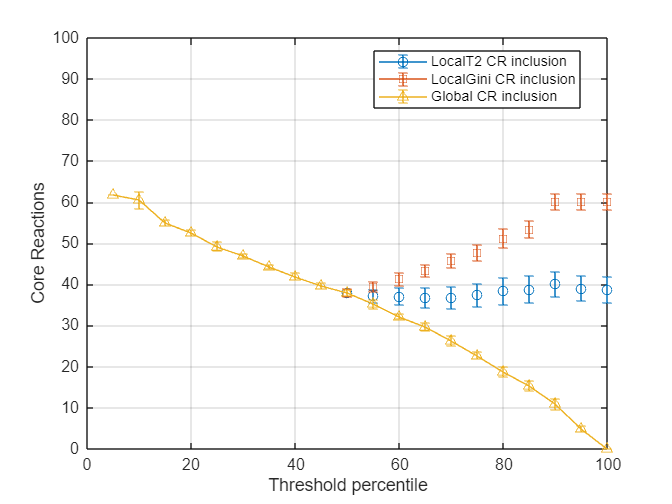

figure;
subplot(1,1,1);
errorbar(upper_p_values(validIndices_Blue), mean_HK_CR_R_all_LT2_expanded(validIndices_Blue), std_HK_CR_R_all_LT2_expanded(validIndices_Blue), '-o', 'DisplayName', 'LocalT2 CR inclusion');
hold on;
errorbar(upper_p_values(validIndices_Red), mean_HK_CR_R_all_LG_expanded(validIndices_Red), std_HK_CR_R_all_LG_expanded(validIndices_Red), '-s', 'DisplayName', 'LocalGini CR inclusion');
errorbar(upper_p_values(validIndices_Yellow), mean_HK_CR_R(validIndices_Yellow), std_HK_CR_R(validIndices_Yellow), '-^', 'DisplayName', 'Global CR inclusion');
hold off;
xlabel("Threshold percentile");
ylabel('Core Reactions');
legend('Location', 'best');
grid on;
ylim([0 100])
xlim([0 100]);
saveas(gcf, 'figure_core_react.png');

## Plot upper threshold vs reaction recall

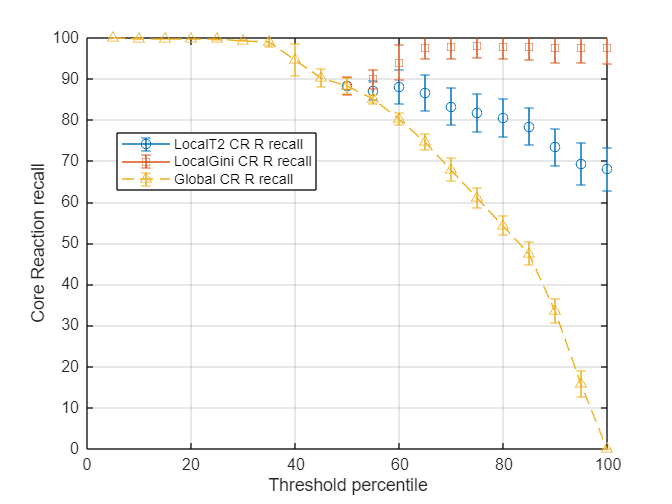

mean_HK_CR_R_recall_values_all_G = mean(HK_CR_R_recall_values_all_G, 1, 'omitnan');
std_HK_CR_R_recall_values_all_G = std(HK_CR_R_recall_values_all_G, 0, 1, 'omitnan');

figure;
subplot(1,1,1);
errorbar(upper_p_values(validIndices_Blue), mean_HK_CR_R_recall_values_all_LT2_expanded(validIndices_Blue), std_HK_CR_R_recall_values_all_LT2_expanded(validIndices_Blue), 'o-', 'DisplayName', 'LocalT2 CR R recall');
hold on;
errorbar(upper_p_values(validIndices_Red), mean_HK_CR_R_recall_values_all_LG_expanded(validIndices_Red), std_HK_CR_R_recall_values_all_LG_expanded(validIndices_Red), 's-', 'DisplayName', 'LocalGini CR R recall');
errorbar(upper_p_values(validIndices_Yellow), mean_HK_CR_R_recall_values_all_G(validIndices_Yellow), std_HK_CR_R_recall_values_all_G(validIndices_Yellow), '^--', 'DisplayName', 'Global CR R recall');
hold off;
xlabel("Threshold percentile");
ylabel('Core Reaction recall');
legend('Location', 'best');
grid on;
xlim([0 100]);
ylim([0 100]);
saveas(gcf, 'figure_recall.png');

## Plot core genes vs core reactions

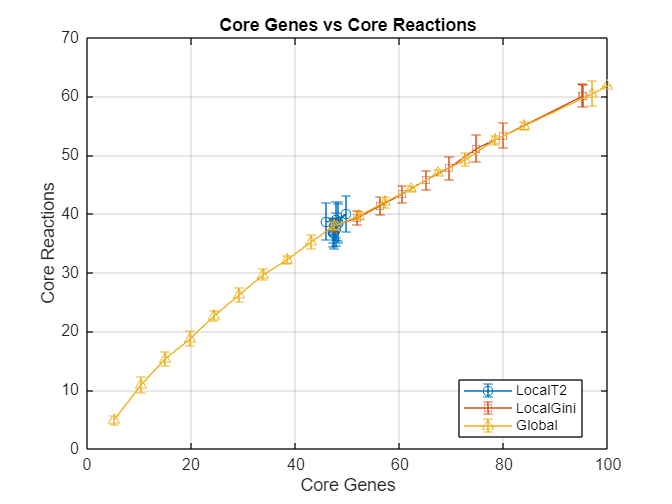

validIndices_LT2 = mean_HK_CG_G_all_LT2 > 0 & mean_HK_CR_R_all_LT2 > 0;
validIndices_LG = mean_HK_CG_G_all_LG > 0 & mean_HK_CR_R_all_LG > 0;
validIndices_G = mean(HK_CG_G_all_G, 1, 'omitnan') > 0 & mean(HK_CR_R_all_G, 1, 'omitnan') > 0;

figure;
errorbar(mean_HK_CG_G_all_LT2(validIndices_LT2), mean_HK_CR_R_all_LT2(validIndices_LT2), std_HK_CR_R_all_LT2(validIndices_LT2), 'o-', 'DisplayName', 'LocalT2');
hold on;
errorbar(mean_HK_CG_G_all_LG(validIndices_LG), mean_HK_CR_R_all_LG(validIndices_LG), std_HK_CR_R_all_LG(validIndices_LG), 's-', 'DisplayName', 'LocalGini');
mean_HK_CG_G_all_G_filtered = mean(HK_CG_G_all_G(:, validIndices_G), 1, 'omitnan');
mean_HK_CR_R_all_G_filtered = mean(HK_CR_R_all_G(:, validIndices_G), 1, 'omitnan');
std_HK_CR_R_all_G_filtered = std(HK_CR_R_all_G(:, validIndices_G), 0, 1, 'omitnan');
errorbar(mean_HK_CG_G_all_G_filtered, mean_HK_CR_R_all_G_filtered, std_HK_CR_R_all_G_filtered, '^-', 'DisplayName', 'Global');
hold off;
xlabel('Core Genes');
ylabel('Core Reactions');
legend('Location', 'best');
grid on;
title('Core Genes vs Core Reactions');
saveas(gcf, 'figure_core_genes_vs_reactions.png');

## Plot core genes vs reaction recall

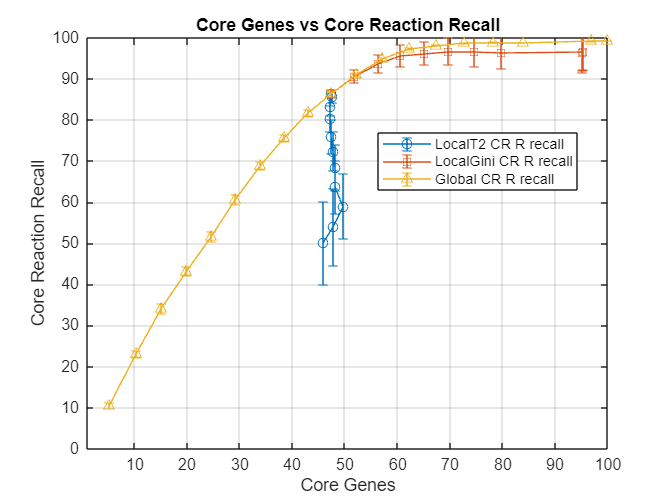

figure;
errorbar(mean_HK_CG_G_all_LT2(validIndices_LT2), mean_HK_CG_G_recall_values_all_LT2(validIndices_LT2), std_HK_CG_G_recall_values_all_LT2(validIndices_LT2), 'o-', 'DisplayName', 'LocalT2 CR R recall');
hold on;
errorbar(mean_HK_CG_G_all_LG(validIndices_LG), mean_HK_CG_G_recall_values_all_LG(validIndices_LG), std_HK_CG_G_recall_values_all_LG(validIndices_LG), 's-', 'DisplayName', 'LocalGini CR R recall');
mean_HK_CG_G_recall_values_all_G_filtered = mean(HK_CG_G_recall_values_all_G(:, validIndices_G), 1, 'omitnan');
std_HK_CG_G_recall_values_all_G_filtered = std(HK_CG_G_recall_values_all_G(:, validIndices_G), 0, 1, 'omitnan');
errorbar(mean_HK_CG_G_all_G_filtered, mean_HK_CG_G_recall_values_all_G_filtered, std_HK_CG_G_recall_values_all_G_filtered, '^-', 'DisplayName', 'Global CR R recall');
hold off;
xlabel('Core Genes');
ylabel('Core Reaction Recall');
legend('Location', 'best');
grid on;
title('Core Genes vs Core Reaction Recall');
xlim([1 100]);
ylim([0 100]);
saveas(gcf, 'figure_core_genes_vs_recall.png');

## Plot upper threshold percentile vs reaction normalized recall

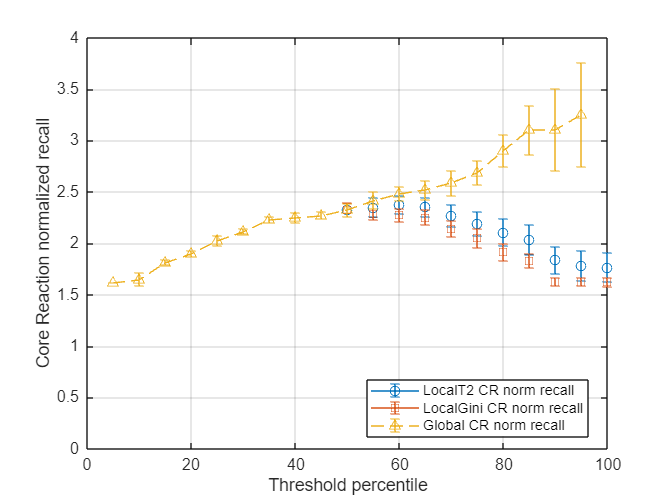

mean_HK_CR_R_recall_norm_all_G = mean(HK_CR_R_recall_norm_all, 1, 'omitnan');
std_HK_CR_R_recall_norm_all_G = std(HK_CR_R_recall_norm_all, 0, 1, 'omitnan');


figure;
subplot(1,1,1);
errorbar(upper_p_values(validIndices_Blue), mean_HK_CR_R_recall_norm_LT2_expanded(validIndices_Blue), std_HK_CR_R_recall_norm_LT2_expanded(validIndices_Blue), 'o-', 'DisplayName', 'LocalT2 CR norm recall');
hold on;
errorbar(upper_p_values(validIndices_Red), mean_HK_CR_R_recall_norm_LG_expanded(validIndices_Red), std_HK_CR_R_recall_norm_LG_expanded(validIndices_Red), 's-', 'DisplayName', 'LocalGini CR norm recall');
errorbar(upper_p_values(validIndices_Yellow), mean_HK_CR_R_recall_norm_all_G(validIndices_Yellow), std_HK_CR_R_recall_norm_all_G(validIndices_Yellow), '^--', 'DisplayName', 'Global CR norm recall');
hold off;
xlabel("Threshold percentile");
ylabel('Core Reaction normalized recall');
legend('Location', 'best');
grid on;
xlim([0 100]);
ylim([0 4]);
saveas(gcf, 'figure_percentile_normrecall.png');

## l

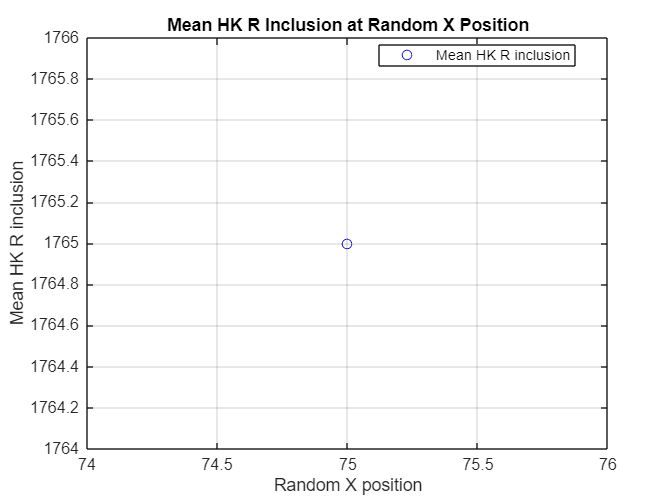

clear all;
close all;
clc;

% Load the data from Excel files
mean_HK_R_inclusion = readtable('Mean_HK_R_inclusion.xlsx');
std_HK_R_inclusion = readtable('Std_HK_R_inclusion.xlsx');

% Random X position (e.g., 75)
x_position = 75;

% Plot mean HK_R inclusion
figure;
plot(x_position, mean_HK_R_inclusion.Mean_HK_R_inclusion, 'bo', 'DisplayName', 'Mean HK R inclusion');
xlabel('Random X position');
ylabel('Mean HK R inclusion');
legend('Location', 'best');
title('Mean HK R Inclusion at Random X Position');
grid on;
saveas(gcf, 'figure_mean_HK_R_inclusion.png');

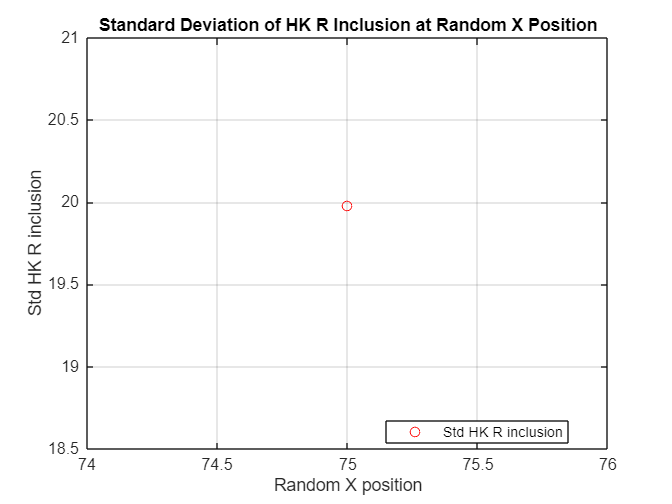


% Plot standard deviation HK_R inclusion
figure;
plot(x_position, std_HK_R_inclusion.Std_HK_R_inclusion, 'ro', 'DisplayName', 'Std HK R inclusion');
xlabel('Random X position');
ylabel('Std HK R inclusion');
legend('Location', 'best');
title('Standard Deviation of HK R Inclusion at Random X Position');
grid on;
saveas(gcf, 'figure_std_HK_R_inclusion.png');

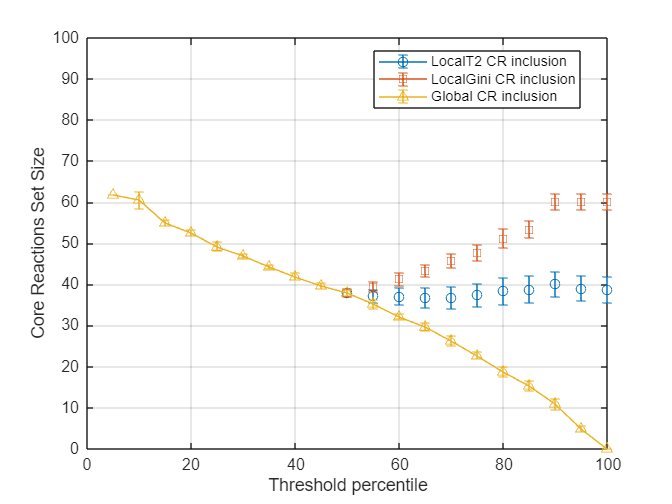


% Load the rest of the data
HK_CR_R_all_G = load("HK_CR_R_all.mat").HK_CR_R_all;
HK_CR_R_recall_values_all_G = load("HK_CR_R_recall_values_all.mat").HK_CR_R_recall_values_all;
HK_CG_G_all_G = load("HK_CG_G_all.mat").HK_CG_G_all;
HK_CG_G_recall_values_all_G = load("HK_CG_G_recall_values_all.mat").HK_CG_G_recall_values_all;
HK_CG_G_recall_norm_all = load('HK_CG_G_recall_norm_all.mat').HK_CG_G_recall_norm_all;
HK_CR_R_recall_norm_all = load('HK_CR_R_recall_norm_all.mat').HK_CR_R_recall_norm_all;
results_LocalT2 = load("results_LocalT2.mat");
results_LocalGini = load("results_LocalGini.mat");

% Obtain the name and change the name for LocalT2
fieldNames = fieldnames(results_LocalT2);
for i = 1:length(fieldNames)
    assignin('base', fieldNames{i}, results_LocalT2.(fieldNames{i}));
end
mean_HK_CG_G_all_LT2 = mean_HK_CG_G_all;
mean_HK_CG_G_recall_values_all_LT2 = mean_HK_CG_G_recall_values_all;
mean_HK_CR_R_all_LT2 = mean_HK_CR_R_all;
mean_HK_CR_R_recall_values_all_LT2 = mean_HK_CR_R_recall_values_all;
std_HK_CG_G_all_LT2 = std_HK_CG_G_all;
std_HK_CG_G_recall_values_all_LT2 = std_HK_CG_G_recall_values_all;
std_HK_CR_R_all_LT2 = std_HK_CR_R_all;
std_HK_CR_R_recall_values_all_LT2 = std_HK_CR_R_recall_values_all;
mean_HK_CR_R_recall_norm_all_LT2 = mean_HK_CR_R_recall_norm_all;
std_HK_CR_R_recall_norm_all_LT2 = std_HK_CR_R_recall_norm_all;

% Obtain the name and change the name for LocalGini
fieldNames = fieldnames(results_LocalGini);
for i = 1:length(fieldNames)
    assignin('base', fieldNames{i}, results_LocalGini.(fieldNames{i}));
end
mean_HK_CG_G_all_LG = mean_HK_CG_G_all;
mean_HK_CG_G_recall_values_all_LG = mean_HK_CG_G_recall_values_all;
mean_HK_CR_R_all_LG = mean_HK_CR_R_all;
mean_HK_CR_R_recall_values_all_LG = mean_HK_CR_R_recall_values_all;
std_HK_CG_G_all_LG = std_HK_CG_G_all;
std_HK_CG_G_recall_values_all_LG = std_HK_CG_G_recall_values_all;
std_HK_CR_R_all_LG = std_HK_CR_R_all;
std_HK_CR_R_recall_values_all_LG = std_HK_CR_R_recall_values_all;
mean_HK_CR_R_recall_norm_all_LG = mean_HK_CR_R_recall_norm_all;
std_HK_CR_R_recall_norm_all_LG = std_HK_CR_R_recall_norm_all;

% Values for upper_p
upper_p_values = 1:1:100;
upper_p_values_LT2_LG = 100:-5:50;

% Obtain the mean and standard deviation
mean_HK_CR_R = mean(HK_CR_R_all_G, 1, 'omitnan');
std_HK_CR_R = std(HK_CR_R_all_G, 0, 1, 'omitnan');
mean_HK_CG_G = mean(HK_CG_G_all_G, 1, 'omitnan');
std_HK_CG_G = std(HK_CG_G_all_G, 0, 1, 'omitnan');

% Expanded data to plot it, for both LocalT2 and LocalGini
% This is done because for both LocalT2 and LocalGini go form 100 to 50, it is necessary to go from 100 to 0
mean_HK_CR_R_all_LT2_expanded = nan(1, length(upper_p_values));
std_HK_CR_R_all_LT2_expanded = nan(1, length(upper_p_values));
mean_HK_CR_R_all_LG_expanded = nan(1, length(upper_p_values));
std_HK_CR_R_all_LG_expanded = nan(1, length(upper_p_values));
mean_HK_CG_G_all_LT2_expanded = nan(1, length(upper_p_values));
std_HK_CG_G_all_LT2_expanded = nan(1, length(upper_p_values));
mean_HK_CG_G_all_LG_expanded = nan(1, length(upper_p_values));
std_HK_CG_G_all_LG_expanded = nan(1, length(upper_p_values));

mean_HK_CR_R_all_LT2_expanded(upper_p_values_LT2_LG) = mean_HK_CR_R_all_LT2;
std_HK_CR_R_all_LT2_expanded(upper_p_values_LT2_LG) = std_HK_CR_R_all_LT2;
mean_HK_CR_R_all_LG_expanded(upper_p_values_LT2_LG) = mean_HK_CR_R_all_LG;
std_HK_CR_R_all_LG_expanded(upper_p_values_LT2_LG) = std_HK_CR_R_all_LG;
mean_HK_CG_G_all_LT2_expanded(upper_p_values_LT2_LG) = mean_HK_CG_G_all_LT2;
std_HK_CG_G_all_LT2_expanded(upper_p_values_LT2_LG) = std_HK_CG_G_all_LT2;
mean_HK_CG_G_all_LG_expanded(upper_p_values_LT2_LG) = mean_HK_CG_G_all_LG;

% Identify valid indexes
validIndices_Yellow = mean_HK_CG_G ~= 0;
validIndices_Red = mean_HK_CR_R_all_LG_expanded ~= 0;
validIndices_Blue = mean_HK_CR_R_all_LT2_expanded ~= 0;

% Create placeholders for the recall values
mean_HK_CR_R_recall_values_all_LT2_expanded = nan(1, length(upper_p_values)); 
std_HK_CR_R_recall_values_all_LT2_expanded = nan(1, length(upper_p_values));   
mean_HK_CR_R_recall_values_all_LG_expanded = nan(1, length(upper_p_values));            
std_HK_CR_R_recall_values_all_LG_expanded = nan(1, length(upper_p_values)); 
mean_HK_CG_G_recall_values_all_LT2_expanded = nan(1, length(upper_p_values)); 
std_HK_CG_G_recall_values_all_LT2_expanded = nan(1, length(upper_p_values));   
mean_HK_CG_G_recall_values_all_LG_expanded = nan(1, length(upper_p_values));            
std_HK_CG_G_recall_values_all_LG_expanded = nan(1, length(upper_p_values)); 

mean_HK_CR_R_recall_values_all_LT2_expanded(upper_p_values_LT2_LG) = mean_HK_CR_R_recall_values_all_LT2;
std_HK_CR_R_recall_values_all_LT2_expanded(upper_p_values_LT2_LG) = std_HK_CR_R_recall_values_all_LT2;
mean_HK_CR_R_recall_values_all_LG_expanded(upper_p_values_LT2_LG) = mean_HK_CR_R_recall_values_all_LG;
std_HK_CR_R_recall_values_all_LG_expanded(upper_p_values_LT2_LG) = std_HK_CR_R_recall_values_all_LG;

mean_HK_CG_G_recall_values_all_LT2_expanded(upper_p_values_LT2_LG) = mean_HK_CG_G_recall_values_all_LT2;
std_HK_CG_G_recall_values_all_LT2_expanded(upper_p_values_LT2_LG) = std_HK_CG_G_recall_values_all_LT2;
mean_HK_CG_G_recall_values_all_LG_expanded(upper_p_values_LT2_LG) = mean_HK_CG_G_recall_values_all_LG;
std_HK_CG_G_recall_values_all_LG_expanded(upper_p_values_LT2_LG) = std_HK_CG_G_recall_values_all_LG;

%% Create the placeholders for the normalized recall values 
mean_HK_CR_R_recall_norm_LT2_expanded = nan(1, length(upper_p_values));
std_HK_CR_R_recall_norm_LT2_expanded = nan(1, length(upper_p_values));
mean_HK_CR_R_recall_norm_LG_expanded = nan(1, length(upper_p_values));
std_HK_CR_R_recall_norm_LG_expanded = nan(1, length(upper_p_values));

mean_HK_CR_R_recall_norm_LT2_expanded(upper_p_values_LT2_LG) = mean_HK_CR_R_recall_norm_all_LT2;
std_HK_CR_R_recall_norm_LT2_expanded(upper_p_values_LT2_LG) = std_HK_CR_R_recall_norm_all_LT2;
mean_HK_CR_R_recall_norm_LG_expanded(upper_p_values_LT2_LG) = mean_HK_CR_R_recall_norm_all_LG;
std_HK_CR_R_recall_norm_LG_expanded(upper_p_values_LT2_LG) = std_HK_CR_R_recall_norm_all_LG;

% Plot upper threshold vs core reaction inclusion
figure;
subplot(1,1,1);
errorbar(upper_p_values(validIndices_Blue), mean_HK_CR_R_all_LT2_expanded(validIndices_Blue), std_HK_CR_R_all_LT2_expanded(validIndices_Blue), '-o', 'DisplayName', 'LocalT2 CR inclusion');
hold on;
errorbar(upper_p_values(validIndices_Red), mean_HK_CR_R_all_LG_expanded(validIndices_Red), std_HK_CR_R_all_LG_expanded(validIndices_Red), '-s', 'DisplayName', 'LocalGini CR inclusion');
errorbar(upper_p_values(validIndices_Yellow), mean_HK_CR_R(validIndices_Yellow), std_HK_CR_R(validIndices_Yellow), '-^', 'DisplayName', 'Global CR inclusion');
hold off;
xlabel("Threshold percentile");
ylabel('Core Reactions Set Size');
legend('Location', 'best');
grid on;
ylim([0 100])
xlim([0 100]);
saveas(gcf, 'figure_core_react.png');


% Plot upper threshold vs reaction recall
mean_HK_CR_R_recall_values_all_G = mean(HK_CR_R_recall_values_all_G, 1, 'omitnan');
std_HK_CR_R_recall_values_all_G = std(HK_CR_R_recall_values_all_G, 0, 1, 'omitnan');

figure;
subplot(1,1,1);
errorbar(upper_p_values(validIndices_Blue), mean_HK_CR_R_recall_values_all_LT2_expanded(validIndices_Blue), std_HK_CR_R_recall_values_all_LT2_expanded(validIndices_Blue), 'o-', 'DisplayName', 'LocalT2 CR R recall');
hold on;
errorbar(upper_p_values(validIndices_Red), mean_HK_CR_R_recall_values_all_LG_expanded(validIndices_Red), std_HK_CR_R_recall_values_all_LG_expanded(validIndices_Red), 's-', 'DisplayName', 'LocalGini CR R recall');
errorbar(upper_p_values(validIndices_Yellow), mean_HK_CR_R_recall_values_all_G(validIndices_Yellow), std_HK_CR_R_recall_values_all_G(validIndices_Yellow), '^--', 'DisplayName', 'Global CR R recall');
hold off;
xlabel("Threshold percentile");
ylabel('Core Reaction recall');
legend('Location', 'best');
grid on;
xlim([0 100]);
ylim([0 100]);
saveas(gcf, 'figure_recall.png');

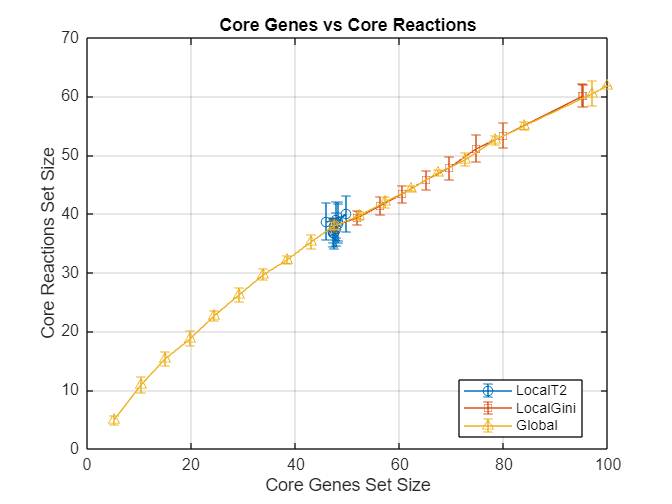


% Plot core genes vs core reactions
validIndices_LT2 = mean_HK_CG_G_all_LT2 > 0 & mean_HK_CR_R_all_LT2 > 0;
validIndices_LG = mean_HK_CG_G_all_LG > 0 & mean_HK_CR_R_all_LG > 0;
validIndices_G = mean(HK_CG_G_all_G, 1, 'omitnan') > 0 & mean(HK_CR_R_all_G, 1, 'omitnan') > 0;

figure;
errorbar(mean_HK_CG_G_all_LT2(validIndices_LT2), mean_HK_CR_R_all_LT2(validIndices_LT2), std_HK_CR_R_all_LT2(validIndices_LT2), 'o-', 'DisplayName', 'LocalT2');
hold on;
errorbar(mean_HK_CG_G_all_LG(validIndices_LG), mean_HK_CR_R_all_LG(validIndices_LG), std_HK_CR_R_all_LG(validIndices_LG), 's-', 'DisplayName', 'LocalGini');
mean_HK_CG_G_all_G_filtered = mean(HK_CG_G_all_G(:, validIndices_G), 1, 'omitnan');
mean_HK_CR_R_all_G_filtered = mean(HK_CR_R_all_G(:, validIndices_G), 1, 'omitnan');
std_HK_CR_R_all_G_filtered = std(HK_CR_R_all_G(:, validIndices_G), 0, 1, 'omitnan');
errorbar(mean_HK_CG_G_all_G_filtered, mean_HK_CR_R_all_G_filtered, std_HK_CR_R_all_G_filtered, '^-', 'DisplayName', 'Global');
hold off;
xlabel('Core Genes Set Size');
ylabel('Core Reactions Set Size');
legend('Location', 'best');
grid on;
title('Core Genes vs Core Reactions');
saveas(gcf, 'figure_core_genes_vs_reactions.png');

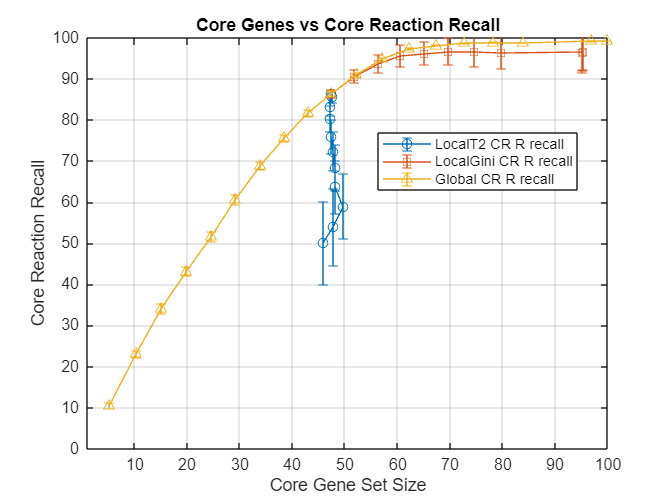


% Plot core genes vs reaction recall
figure;
errorbar(mean_HK_CG_G_all_LT2(validIndices_LT2), mean_HK_CG_G_recall_values_all_LT2(validIndices_LT2), std_HK_CG_G_recall_values_all_LT2(validIndices_LT2), 'o-', 'DisplayName', 'LocalT2 CR R recall');
hold on;
errorbar(mean_HK_CG_G_all_LG(validIndices_LG), mean_HK_CG_G_recall_values_all_LG(validIndices_LG), std_HK_CG_G_recall_values_all_LG(validIndices_LG), 's-', 'DisplayName', 'LocalGini CR R recall');
mean_HK_CG_G_recall_values_all_G_filtered = mean(HK_CG_G_recall_values_all_G(:, validIndices_G), 1, 'omitnan');
std_HK_CG_G_recall_values_all_G_filtered = std(HK_CG_G_recall_values_all_G(:, validIndices_G), 0, 1, 'omitnan');
errorbar(mean_HK_CG_G_all_G_filtered, mean_HK_CG_G_recall_values_all_G_filtered, std_HK_CG_G_recall_values_all_G_filtered, '^-', 'DisplayName', 'Global CR R recall');
hold off;
xlabel('Core Gene Set Size');
ylabel('Core Reaction Recall');
legend('Location', 'best');
grid on;
title('Core Genes vs Core Reaction Recall');
xlim([1 100]);
ylim([0 100]);
saveas(gcf, 'figure_core_genes_vs_recall.png');

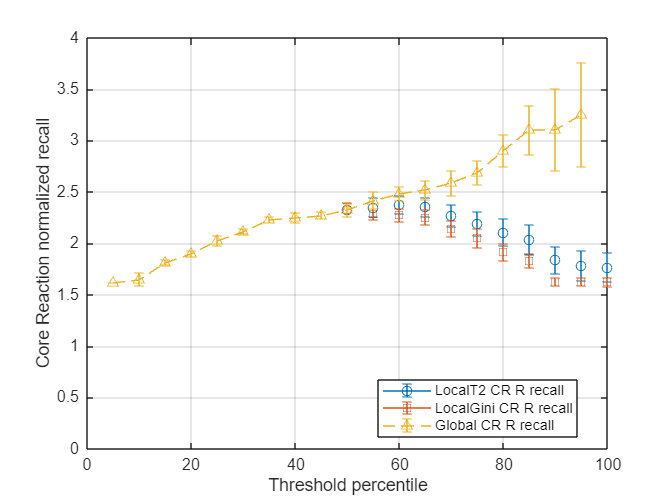


% Plot upper threshold percentile vs reaction normalized recall
mean_HK_CR_R_recall_norm_all_G = mean(HK_CR_R_recall_norm_all, 1, 'omitnan');
std_HK_CR_R_recall_norm_all_G = std(HK_CR_R_recall_norm_all, 0, 1, 'omitnan');

figure;
subplot(1,1,1);
errorbar(upper_p_values(validIndices_Blue), mean_HK_CR_R_recall_norm_LT2_expanded(validIndices_Blue), std_HK_CR_R_recall_norm_LT2_expanded(validIndices_Blue), 'o-', 'DisplayName', 'LocalT2 CR R recall');
hold on;
errorbar(upper_p_values(validIndices_Red), mean_HK_CR_R_recall_norm_LG_expanded(validIndices_Red), std_HK_CR_R_recall_norm_LG_expanded(validIndices_Red), 's-', 'DisplayName', 'LocalGini CR R recall');
errorbar(upper_p_values(validIndices_Yellow), mean_HK_CR_R_recall_norm_all_G(validIndices_Yellow), std_HK_CR_R_recall_norm_all_G(validIndices_Yellow), '^--', 'DisplayName', 'Global CR R recall');
hold off;
xlabel("Threshold percentile");
ylabel('Core Reaction normalized recall');
legend('Location', 'best');
grid on;
xlim([0 100]);
ylim([0 4]);
saveas(gcf, 'figure_percentile_normrecall.png');